## K-Subspaces (KSS) Clustering Demo on Hyperspectral Datasets

###         This Live Script lets you:

- Choose a dataset (Pavia, PaviaUni, Salinas, Indian Pines)

-  Run KSS on the filtered pixels i.e., foreground pixels

- Visualize the resulting cluster map

### Dropdown to select desired dataset

% % Dataset Configuration

this_script_path = matlab.desktop.editor.getActiveFilename;
this_script_folder = fileparts(this_script_path);
proj_root = fileparts(this_script_folder);
addpath(fullfile(proj_root, "KSS_MATLAB"));

clear; clc;

DATASETS = struct( ...
    'Pavia', struct( ...
    'data_file', "Pavia.mat", ...
    'gt_file', "Pavia_gt.mat", ...
    'data_key', "pavia", ...
    'gt_key', "pavia_gt"), ...
    'PaviaUni', struct( ...
    'data_file', "PaviaUni.mat", ...
    'gt_file', "PaviaU_gt.mat", ...
    'data_key', "paviaU", ...
    'gt_key', "paviaU_gt"), ...
    'Salinas', struct( ...
    'data_file', "Salinas_corrected.mat", ...
    'gt_file', "Salinas_gt.mat", ...
    'data_key', "salinas_corrected", ...
    'gt_key', "salinas_gt"), ...
    'Indian_pines', struct( ...
    'data_file', "Indian_pines.mat", ...
    'gt_file', "Indian_pines_gt.mat", ...
    'data_key', "indian_pines", ...
    'gt_key', "indian_pines_gt") ...
);


ds_name = "Indian_pines";


### Function to run KSS on remote sensing datasets

function run_kss_hsi(ds_name, DATASETS)

    cfg = DATASETS.(ds_name);

    % Load Data and Ground Truth

    data_struct = load(fullfile("MAT Files", cfg.data_file));
    gt_struct = load(fullfile("GT Files", cfg.gt_file));

    data_cube = data_struct.(cfg.data_key);
    gt_data = gt_struct.(cfg.gt_key);

    [H, W, B] = size(data_cube);

    % Mask to remove the background pixels

    mask_fg  = gt_data ~= 0;
    mask_vec = mask_fg(:);

    % Determine K from unique non-zero labels

    gt_labels = unique(gt_data);
    gt_labels(gt_labels == 0) = [];
    K = numel(gt_labels);

    % Reshape the data cube to a matrix (D x N)
    % D = Bands; N=pixels
    X_full = reshape(data_cube, [], B);
    X_full = X_full.';
    X = X_full(:, mask_vec);

    % KSS parameters
    r     = 2;
    nInit = 25;

    % Run KSS
    [~, c, totalcost] = kss(X, K, r, 'NInit', nInit, 'Verbose', true);
    
    fprintf('Dataset: %s\n', ds_name);
    fprintf('Best total cost over %d inits: %.6e\n', nInit, totalcost);
    

    % Map cluster labels back to image grid
    c_image_vec = zeros(H*W, 1);
    c_image_vec(mask_vec) = c;
    c_image = reshape(c_image_vec, H, W);

    % Colormap: black for background + K distinct colors
    colors = lines(K);
    cmap   = [0 0 0; colors];

    figure;
    imagesc(c_image);
    axis image off;
    title(sprintf('KSS clustering on %s (K = %d, r = %d)', ds_name, K, r));
    colormap(cmap);
    colorbar;
end

### Run KSS button

Iter 1: cluster 2 empty, reinitializing.
Iter 1: cluster 4 empty, reinitializing.
Iter 1: cluster 5 empty, reinitializing.
Iter 1: cluster 6 empty, reinitializing.
Iter 1: cluster 7 empty, reinitializing.
Iter 1: cluster 8 empty, reinitializing.
Iter 1: cluster 9 empty, reinitializing.
Iter 1: cluster 10 empty, reinitializing.
Iter 1: cluster 11 empty, reinitializing.
Iter 1: cluster 13 empty, reinitializing.
Iter 1: cluster 14 empty, reinitializing.
Iter 1: cluster 16 empty, reinitializing.
Iter 2: cluster 2 empty, reinitializing.
Iter 2: cluster 4 empty, reinitializing.
Iter 2: cluster 5 empty, reinitializing.
Iter 2: cluster 6 empty, reinitializing.
Iter 2: cluster 7 empty, reinitializing.
Iter 2: cluster 8 empty, reinitializing.
Iter 2: cluster 9 empty, reinitializing.
Iter 2: cluster 10 empty, reinitializing.
Iter 2: cluster 11 empty, reinitializing.
Iter 2: cluster 13 empty, reinitializing.
Iter 2: cluster 14 empty, reinitializing.
Iter 2: cluster 16 empty, reinitializing.
Iter 3

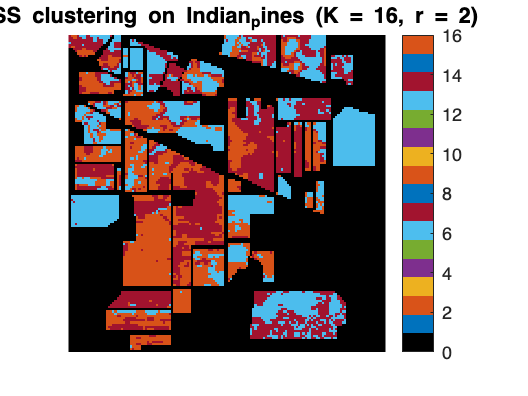

run_kss_hsi(ds_name, DATASETS); 